clc;clear;close all;tic
rng(42)

####  DATASET CONFIGURATION


Dataset_root = "C:\Users\pooji\OneDrive\Desktop\MFC4\EuroSAT";
Dataset_path = Dataset_root;

Classes = {'Highway','Residential','Forest','SeaLake','River'};
Images_per_class = 400;
Num_clusters = 5;

#### LOAD DATASET



imds = imageDatastore(Dataset_path,...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

% keep only selected classes
imds = subset(imds, ismember(imds.Labels, Classes));

imds.Labels = removecats(imds.Labels);

% select equal number of images
imds = splitEachLabel(imds, Images_per_class,'randomized');

disp("Total images loaded:")

Total images loaded:


disp(numel(imds.Files))

        2000




countEachLabel(imds)

ans = 5×2 table
       Label       Count
    ___________    _____

    Forest          400 
    Highway         400 
    Residential     400 
    River           400 
    SeaLake         400 



labels = grp2idx(imds.Labels);

#### MODELS TO COMPARE

**Feature Vector Dimension**

The dimensionality of the extracted features depends on the architecture of the ResNet model.

ResNet18 → 2000 × 512 feature matrix

ResNet50 → 2000 × 2048 feature matrix

ResNet101 → 2000 × 2048 feature matrix


models = {'resnet18','resnet50','resnet101'};

results = zeros(length(models),3);

% LOOP OVER MODELS

for m = 1:length(models)

    model_name = models{m};

    disp("===================================")
    disp("Running model: " + model_name)

    % load network
    net = eval(model_name);

    inputSize = net.Layers(1).InputSize(1:2);

    augimds = augmentedImageDatastore(inputSize, imds);

    % select feature layer
    if strcmp(model_name,'resnet50')
        featureLayer = 'avg_pool';
    else
        featureLayer = 'pool5';
    end

Running model: resnet18


Running model: resnet50


Running model: resnet101


**Deep Feature Extraction**

Deep convolutional neural networks such as ResNet are capable of learning hierarchical representations of images. Instead of using raw pixel values, we extract high-level feature embeddings from a pretrained network.

In this work, three pretrained models were evaluated:

- ResNet18

- ResNet50

- ResNet101

These networks were originally trained on the ImageNet dataset and therefore capture rich visual representations such as edges, textures, shapes, and semantic structures.

The features were extracted from the **final global pooling layer** of each network.

% FEATURE EXTRACTION
   

    features = activations(net,augimds,featureLayer,...
        'MiniBatchSize',32,...
        'ExecutionEnvironment','gpu');

    features = squeeze(features);

    X = gather(features)';

    disp("Feature size:")
    disp(size(X))

Feature size:


        2000         512



Feature size:


        2000        2048



Feature size:


        2000        2048



**Clustering of Deep Features**

After extracting feature embeddings from the neural network, clustering is performed to group similar images together.

In this experiment, **K-Means clustering** was used with the number of clusters equal to the number of classes.

The K-Means algorithm works by:

- Initializing cluster centroids

- Assigning each sample to the nearest centroid

- Updating the centroids

- Repeating until convergence

The clustering process groups images with similar deep features.


    % KMEANS CLUSTERING
    

    idx = kmeans(X,Num_clusters,...
        'Replicates',10,...
        'MaxIter',1000);

    % METRICS
    %

    acc = clustering_accuracy(labels,idx);
    nmi_score = nmi(labels,idx);
    ari_val = ari_score(labels,idx);

    results(m,:) = [acc nmi_score ari_val];

    disp("ACC:")
    disp(acc)

end

ACC:


    0.8455



ACC:


    0.8580



ACC:


    0.8545



**Clustering Evaluation Metrics**

To evaluate clustering performance, three standard metrics were used:

**1.Clustering Accuracy (ACC)**

Measures the percentage of samples correctly assigned to clusters after optimal label matching.

                    
$$ACC$$

$$=\frac\text{correctly clustered samples} {total samples}$$


**2.Normalized Mutual Information (NMI)**

Measures how much information the predicted clusters share with the ground-truth labels.

`0 → independent clusters`

`1 → perfect clustering`

**3️. Adjusted Rand Index (ARI)**

Measures clustering similarity based on pairwise sample relationships.

It evaluates how many pairs of samples are correctly grouped together.

#### RESULTS


disp(" ")

disp("===== RESNET MODEL COMPARISON =====")

===== RESNET MODEL COMPARISON =====



T = table(models',results(:,1),results(:,2),results(:,3),...
    'VariableNames',{'Model','ACC','NMI','ARI'});

disp(T)

        Model         ACC        NMI        ARI  
    _____________    ______    _______    _______

    {'resnet18' }    0.8455    0.73159     0.6981
    {'resnet50' }     0.858    0.75136    0.71745
    {'resnet101'}    0.8545    0.72961    0.69516



**Experimental Results**

The performance of each ResNet model was evaluated using clustering accuracy, normalized mutual information, and adjusted Rand index.

These results indicate that **ResNet50 produces the most discriminative feature embeddings for the EuroSAT dataset**.

Although ResNet101 is deeper, it does not significantly outperform ResNet50.

This suggests that **ResNet50 provides a good balance between feature richness and computational efficiency**.

#### PLOT COMPARISON

**Visualization of Model Comparison**

A bar plot was used to visualize clustering accuracy across the different ResNet models.

The plot shows that:

- ResNet50 achieves the highest accuracy

- ResNet18 produces slightly lower accuracy due to smaller feature dimension

- ResNet101 performs similarly to ResNet50 but with higher computational cost

Thus, ResNet50 was selected as the primary feature extractor for the main clustering experiments.

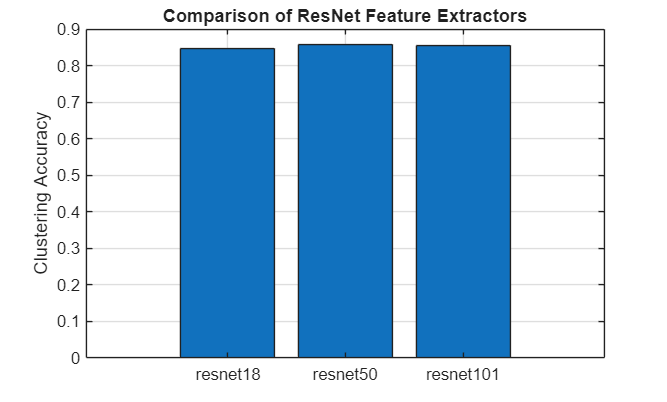

figure
bar(results(:,1))
set(gca,'XTickLabel',models)
ylabel('Clustering Accuracy')
title('Comparison of ResNet Feature Extractors')
grid on

% FUNCTION : CLUSTERING ACCURACY


function acc = clustering_accuracy(y_true, y_pred)

Elapsed time is 37.990869 seconds.



y_true = y_true(:);
y_pred = y_pred(:);

cm = confusionmat(y_true,y_pred);

correct = sum(max(cm,[],2));

acc = correct/length(y_true);

end



% FUNCTION : NMI


function score = nmi(y_true,y_pred)

y_true = y_true(:);
y_pred = y_pred(:);

N = length(y_true);

cm = confusionmat(y_true,y_pred);

ni = sum(cm,2);
nj = sum(cm,1);

MI = 0;

for i=1:size(cm,1)
    for j=1:size(cm,2)

        if cm(i,j)>0

            MI = MI + (cm(i,j)/N)*...
                log((N*cm(i,j))/(ni(i)*nj(j)));

        end

    end
end

H_true = -sum((ni/N).*log(ni/N));
H_pred = -sum((nj/N).*log(nj/N));

score = MI/sqrt(H_true*H_pred);

end




% FUNCTION : ARI


function score = ari_score(y_true,y_pred)

y_true = y_true(:);
y_pred = y_pred(:);

N = length(y_true);

cm = confusionmat(y_true,y_pred);

sum_comb_c = sum(nchoosek_vector(sum(cm,2)));
sum_comb_k = sum(nchoosek_vector(sum(cm,1)));
sum_comb = sum(nchoosek_vector(cm(:)));

total_comb = nchoosek(N,2);

expected_index = (sum_comb_c*sum_comb_k)/total_comb;

max_index = 0.5*(sum_comb_c+sum_comb_k);

score = (sum_comb-expected_index)/(max_index-expected_index);

end


function s = nchoosek_vector(v)

s = v.*(v-1)/2;

end
toc

**Conclusion**

In this study, multiple pretrained ResNet architectures were evaluated for deep feature extraction on the EuroSAT dataset. The extracted features were clustered using K-Means, and clustering performance was evaluated using ACC, NMI, and ARI metrics.

Among the evaluated models, **ResNet50 achieved the best clustering performance**, indicating that its feature representations are well suited for capturing structural patterns in satellite imagery.

Therefore, ResNet50 was selected as the feature extractor for subsequent spectral clustering experiments.